load('single_class_objdet_gTruth.mat')

[imds,blds] = objectDetectorTrainingData(gTruth);
inputSize = [227 227 3];

% dataSource = gTruth.DataSource;
% labelDefs  = gTruth.LabelDefinitions;
% labelData  = gTruth.LabelData;
% labelDefs.Name = strrep(labelDefs.Name, labelDefs.Name, 'tank');
% varnames = labelData.Properties.VariableNames;
% labelData.Properties.VariableNames = strrep(labelData.Properties.VariableNames, varnames, 'tank');
% % gTruth = groundTruth(dataSource, labelDefs, labelData);

numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
numTrain = round(0.70 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 20% of the images for validation
numVal = round(0.10 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% %replace all labels with "tank"
% replacedlabels = {};
% for i = 1:size(blds.LabelData,1)
%     cat = blds.LabelData{i,2};
%     for j = 1:size(cat)
%       cat(j) = "tank";
%     end
%     replacedLabels{i,1} = cat;
% end
% tbl = cell2table(blds.LabelData)
% tbl.Var2 = replacedLabels;

tbl = 580×2 table
           Var1                  Var2       
    ___________________    _________________

    {2×4 double       }    {2×1 categorical}
    {[ 81 349 516 284]}    {[tank         ]}
    {[ 75 153 379 302]}    {[tank         ]}
    {2×4 double       }    {2×1 categorical}
    {[  67 56 533 244]}    {[tank         ]}
    {[521 284 198 252]}    {[tank         ]}
    {[   1 2 1176 764]}    {[tank         ]}
    {[    5 1 794 794]}    {[tank         ]}
    {2×4 double       }    {2×1 categorical}
    {2×4 double       }    {2×1 categorical}
    {2×4 double       }    {2×1 categorical}
    {2×4 double       }    {2×1 categorical}
    {[109 244 225 128]}    {[tank         ]}
    {[ 76 225 388 274]}    {[tank         ]}
    {[467 217 151 127]}    {[tank         ]}
    {[488 180 270 194]}    {[tank         ]}


% tblds = boxLabelDatastore(tbl);
% %transblds = transform(blds,(@LabelData)replaceLabels(LabelData,'tank'));
% newgTruth = groundTruth()

bldsTrain = blds.subset(trainingIdx);
bldsVal = blds.subset(valIdx);
bldsTest = blds.subset(testIdx);

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsVal,bldsVal);
testData = combine(imdsTest,bldsTest);

%validateInputData(trainingData);
%validateInputData(validationData);
%validateInputData(testData);

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,"Rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);

figure
imshow(annotatedImage)
reset(trainingData);

%className = "tank";
classNames = gTruth.LabelDefinitions.Name;
numClasses = numel(classNames);

tbl = countEachLabel(blds)

tbl = 19×3 table
     Label      Count    ImageCount
    ________    _____    __________

    t64a          0          0     
    t64bv         0          0     
    t72a          0          0     
    t72av         0          0     
    t72b          0          0     
    t72b3         0          0     
    t72b3obr      0          0     
    t72ba         0          0     
    t72bobr       0          0     
    t80bv         0          0     
    t80bvk        0          0     
    t80bvm        0          0     
    t80u          0          0     
    t80ue         0          0     
    t80uk         0          0     
    t80um         0          0     


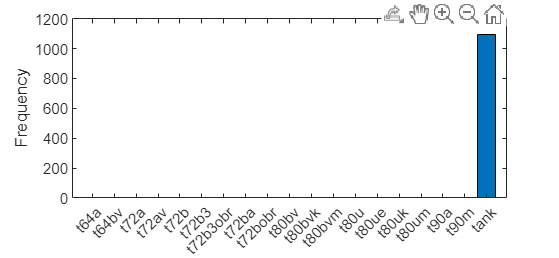

bar(tbl.Label,tbl.Count)
ylabel("Frequency")

%JUST MAKES THINGS WORSE

%Balancing Box Label Classes
% cvBefore = std(tbl.Count)/mean(tbl.Count)
% numObservations = mean(tbl.Count) * numClasses;
% ThresholdValue = 0.5;
% 
% blockedImages = blockedImage(imds.Files,BlockSize=[50,50]);
% blockSize = [50,50];
%boxLabels = cell2table(blds.LabelData);

% locationSet = balanceBoxLabels(boxLabels,blockedImages,blockSize,...
%         numObservations,'OverlapThreshold',ThresholdValue);

% bldsBalanced = boxLabelDatastore(boxLabels,locationSet);
% balancedDatasetCount = countEachLabel(bldsBalanced);

% hold on;
% balancedLabels = balancedDatasetCount.Label;
% balancedCount  = balancedDatasetCount.Count;
% h2 = histogram('Categories',balancedLabels,'BinCounts',balancedCount);
% % title(h2.Parent,"Balanced class labels (OverlapThreshold: " + ThresholdValue + ")" );
% legend(h2.Parent,{'Before','After'});

% cvAfter = std(balancedCount)/mean(balancedCount)

trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 6;
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);

area = anchors(:, 1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);

anchorBoxes = {anchors(1:3,:)
    anchors(4:6,:)
    };

network = squeezenet; %resnet50();
detector = yolov3ObjectDetector(network, classNames, anchorBoxes, 'DetectionNetworkSource', {'fire9-concat', 'fire5-concat'}, InputSize = inputSize);
%featureLayer = "activation_40_relu";
%lgraph = yolov2Layers(inputSize, numClasses, anchors, network, featureLayer);   

%detector = yolov4ObjectDetector("tiny-yolov4-coco",classNames,anchorBoxes,InputSize=inputSize);

augmentedTrainingData = transform(trainingData,@augmentData);

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,BorderSize=10)

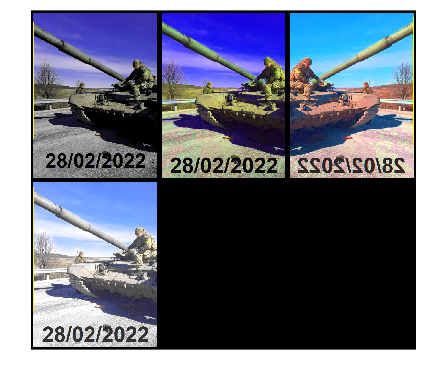

%yolov3 training options
numEpochs = 200;
miniBatchSize = 8;

learningRate = 0.001;
warmupPeriod = 1000;
l2Regularization = 0.0005;
penaltyThreshold = 0.5;
velocity = [];
preprocessedTrainingData = transform(augmentedTrainingData, @(data)preprocess(detector, data));
mbqTrain = minibatchqueue(preprocessedTrainingData, 2,...
        "MiniBatchSize", miniBatchSize,...
        "MiniBatchFcn", @(images, boxes, labels) createBatchData(images, boxes, labels, classNames), ...
        "MiniBatchFormat", ["SSCB", ""],...
        "DispatchInBackground", true,...
        "OutputCast", ["", "double"]);

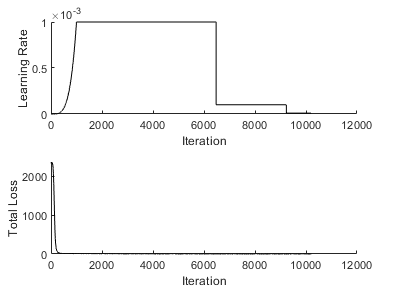

Epoch : 1 | Iteration : 1 | Learning Rate : 1e-15 | Total Loss : 2354.3494 | Box Loss : 4.6631 | Object Loss : 2348.0481 | Class Loss : 1.6383
Epoch : 1 | Iteration : 2 | Learning Rate : 1.6e-14 | Total Loss : 2351.9805 | Box Loss : 2.696 | Object Loss : 2348.3142 | Class Loss : 0.97031
Epoch : 1 | Iteration : 3 | Learning Rate : 8.1e-14 | Total Loss : 2339.873 | Box Loss : 3.2508 | Object Loss : 2335.7478 | Class Loss : 0.87461
Epoch : 1 | Iteration : 4 | Learning Rate : 2.56e-13 | Total Loss : 2340.5244 | Box Loss : 3.8648 | Object Loss : 2335.8352 | Class Loss : 0.8245
Epoch : 1 | Iteration : 5 | Learning Rate : 6.25e-13 | Total Loss : 2338.1487 | Box Loss : 2.477 | Object Loss : 2335.1646 | Class Loss : 0.50714
Epoch : 1 | Iteration : 6 | Learning Rate : 1.296e-12 | Total Loss : 2337.1333 | Box Loss : 3.3875 | Object Loss : 2332.5991 | Class Loss : 1.1467
Epoch : 1 | Iteration : 7 | Learning Rate : 2.401e-12 | Total Loss : 2353.6909 | Box Loss : 3.1454 | Object Loss : 2349.5952 | C

fig = figure;
[lossPlotter, learningRatePlotter] = configureTrainingProgressPlotter(fig);

iteration = 0;
% Custom training loop.
for epoch = 1:numEpochs
      
    reset(mbqTrain);
    shuffle(mbqTrain);
    
    while(hasdata(mbqTrain))
        iteration = iteration + 1;
       
        [XTrain, YTrain] = next(mbqTrain);
        
        % Evaluate the model gradients and loss using dlfeval and the
        % modelGradients function.
        [gradients, state, lossInfo] = dlfeval(@modelGradients, detector, XTrain, YTrain, penaltyThreshold);

        % Apply L2 regularization.
        gradients = dlupdate(@(g,w) g + l2Regularization*w, gradients, detector.Learnables);

        % Determine the current learning rate value.
        currentLR = piecewiseLearningRateWithWarmup(iteration, epoch, learningRate, warmupPeriod, numEpochs);

        % Update the detector learnable parameters using the SGDM optimizer.
        [detector.Learnables, velocity] = sgdmupdate(detector.Learnables, gradients, velocity, currentLR);

        % Update the state parameters of dlnetwork.
        detector.State = state;
          
        % Display progress.
        displayLossInfo(epoch, iteration, currentLR, lossInfo);  
            
        % Update training plot with new points.
        updatePlots(lossPlotter, learningRatePlotter, iteration, currentLR, lossInfo.totalLoss);
    end        
end

options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="piecewise",...
    MiniBatchSize=4,...
    L2Regularization=0.0005,...
    MaxEpochs=110,...
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=false,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=20,...
    CheckpointPath=fullfile("./Checkpoints/"),...
    ValidationData=validationData,...
    OutputNetwork="best-validation-loss",...
    ExecutionEnvironment="auto");

% [detector,info] = trainYOLOv4ObjectDetector(augmentedTrainingData,detector,options);
[detector, info] = trainYOLOv2ObjectDetector(augmentedTrainingData,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* tank

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |        20.53 |        22.60 |     421.3938 |     510.8353 |          0.0010 |
|       1 |          20 |       00:00:51 |         2.14 |              |       4.5985 |              |          0.0010 |
|       1 |          40 |       00:01:33 |         2.24 |  

I = imread("russia/russia/Tanks/Unknown/Unknown_tank_3f3.jpg");
[bboxes,scores,labels] = detect(detector,I,Threshold=0.2);

I = insertObjectAnnotation(I,"rectangle",bboxes,labels);
figure
imshow(I)

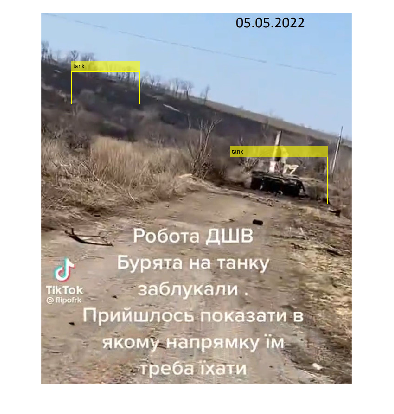

preprocessedTestData = transform(testData, @(data)resizeImageAndLabel(data, inputSize));
results = detect(detector,preprocessedTestData, MiniBatchSize=4, Threshold=0.07);
[ap, precision, recall] = evaluateDetectionPrecision(results, preprocessedTestData);

classID = 1;
figure
plot(recall,precision)
xlabel("Recall")
ylabel("Precision")
grid on
title(sprintf("Average Precision = %.2f",ap(classID)))

%Quantize network
quantObj = dlquantizer(detector,"ExecutionEnvironment","FPGA");

[calibrationData,validationData] = splitEachLabel(imageData,0.5,'randomized');

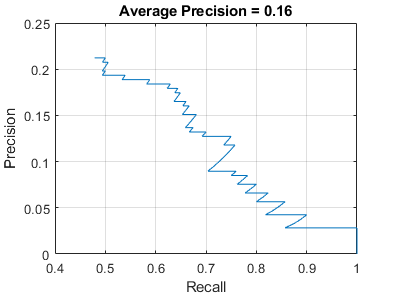

hPC = dlhdl.ProcessorConfig('Bitstream', 'zcu102_single');

simObj = dlhdl.Simulator('Network',netTransfer,'ProcessorConfig',hPC);

function data = replaceLabels(data, lbl)
    for i = 1:size(data.LabelData,1)
        cat = data.LabelData{i,2};
        for j = 1:size(cat)
            cat(j) = lbl;
        end
        data.LabelData{i,1} = cat;
    end
end
function currentLR = piecewiseLearningRateWithWarmup(iteration, epoch, learningRate, warmupPeriod, numEpochs)
    % The piecewiseLearningRateWithWarmup function computes the current
    % learning rate based on the iteration number.
    persistent warmUpEpoch;
    
    if iteration <= warmupPeriod
        % Increase the learning rate for number of iterations in warmup period.
        currentLR = learningRate * ((iteration/warmupPeriod)^4);
        warmUpEpoch = epoch;
    elseif iteration >= warmupPeriod && epoch < warmUpEpoch+floor(0.6*(numEpochs-warmUpEpoch))
        % After warm up period, keep the learning rate constant if the remaining number of epochs is less than 60 percent. 
        currentLR = learningRate;
        
    elseif epoch >= warmUpEpoch + floor(0.6*(numEpochs-warmUpEpoch)) && epoch < warmUpEpoch+floor(0.9*(numEpochs-warmUpEpoch))
        % If the remaining number of epochs is more than 60 percent but less
        % than 90 percent multiply the learning rate by 0.1.
        currentLR = learningRate*0.1;
        
    else
        % If remaining epochs are more than 90 percent multiply the learning
        % rate by 0.01.
        currentLR = learningRate*0.01;
    end
end
function [gradients, state, info] = modelGradients(detector, XTrain, YTrain, penaltyThreshold)
inputImageSize = size(XTrain,1:2);

% Gather the ground truths in the CPU for post processing
YTrain = gather(extractdata(YTrain));

% Extract the predictions from the detector.
[gatheredPredictions, YPredCell, state] = forward(detector, XTrain);

% Generate target for predictions from the ground truth data.
[boxTarget, objectnessTarget, classTarget, objectMaskTarget, boxErrorScale] = generateTargets(gatheredPredictions,...
    YTrain, inputImageSize, detector.AnchorBoxes, penaltyThreshold);

% Compute the loss.
boxLoss = bboxOffsetLoss(YPredCell(:,[2 3 7 8]),boxTarget,objectMaskTarget,boxErrorScale);
objLoss = objectnessLoss(YPredCell(:,1),objectnessTarget,objectMaskTarget);
clsLoss = classConfidenceLoss(YPredCell(:,6),classTarget,objectMaskTarget);
totalLoss = boxLoss + objLoss + clsLoss;

info.boxLoss = boxLoss;
info.objLoss = objLoss;
info.clsLoss = clsLoss;
info.totalLoss = totalLoss;

% Compute gradients of learnables with regard to loss.
gradients = dlgradient(totalLoss, detector.Learnables);
end

function boxLoss = bboxOffsetLoss(boxPredCell, boxDeltaTarget, boxMaskTarget, boxErrorScaleTarget)
% Mean squared error for bounding box position.
lossX = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,1),boxDeltaTarget(:,1),boxMaskTarget(:,1),boxErrorScaleTarget));
lossY = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,2),boxDeltaTarget(:,2),boxMaskTarget(:,1),boxErrorScaleTarget));
lossW = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,3),boxDeltaTarget(:,3),boxMaskTarget(:,1),boxErrorScaleTarget));
lossH = sum(cellfun(@(a,b,c,d) mse(a.*c.*d,b.*c.*d),boxPredCell(:,4),boxDeltaTarget(:,4),boxMaskTarget(:,1),boxErrorScaleTarget));
boxLoss = lossX+lossY+lossW+lossH;
end

function objLoss = objectnessLoss(objectnessPredCell, objectnessDeltaTarget, boxMaskTarget)
% Binary cross-entropy loss for objectness score.
objLoss = sum(cellfun(@(a,b,c) crossentropy(a.*c,b.*c,'TargetCategories','independent'),objectnessPredCell,objectnessDeltaTarget,boxMaskTarget(:,2)));
end

function clsLoss = classConfidenceLoss(classPredCell, classTarget, boxMaskTarget)
% Binary cross-entropy loss for class confidence score.
clsLoss = sum(cellfun(@(a,b,c) crossentropy(a.*c,b.*c,'TargetCategories','independent'),classPredCell,classTarget,boxMaskTarget(:,3)));
end

function [XTrain, YTrain] = createBatchData(data, groundTruthBoxes, groundTruthClasses, classNames)
% Returns images combined along the batch dimension in XTrain and
% normalized bounding boxes concatenated with classIDs in YTrain

% Concatenate images along the batch dimension.
XTrain = cat(4, data{:,1});

% Get class IDs from the class names.
classNames = repmat({categorical(classNames')}, size(groundTruthClasses));
[~, classIndices] = cellfun(@(a,b)ismember(a,b), groundTruthClasses, classNames, 'UniformOutput', false);

% Append the label indexes and training image size to scaled bounding boxes
% and create a single cell array of responses.
combinedResponses = cellfun(@(bbox, classid)[bbox, classid], groundTruthBoxes, classIndices, 'UniformOutput', false);
len = max( cellfun(@(x)size(x,1), combinedResponses ) );
paddedBBoxes = cellfun( @(v) padarray(v,[len-size(v,1),0],0,'post'), combinedResponses, 'UniformOutput',false);
YTrain = cat(4, paddedBBoxes{:,1});
end
function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    bboxes = A{ii,2};
    labels = A{ii,3};
    sz = size(I);

    if numel(sz) == 3 && sz(3) == 3
        I = jitterColorHSV(I,...
            contrast=0.0,...
            Hue=0.1,...
            Saturation=0.2,...
            Brightness=0.2);
    end
    
    % Randomly flip image.
    tform = randomAffine2d(XReflection=true,Scale=[1 1.1]);
    rout = affineOutputView(sz,tform,BoundsStyle="centerOutput");
    I = imwarp(I,tform,OutputView=rout);
    
    % Apply same transform to boxes.
    [bboxes,indices] = bboxwarp(bboxes,tform,rout,OverlapThreshold=0.25);
    labels = labels(indices);
    
    % Return original data only when all boxes are removed by warping.
    if isempty(indices)
        data(ii,:) = A(ii,:);
    else
        data(ii,:) = {I,bboxes,labels};
    end
end
end

function data = preprocessData(data,targetSize)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.

for ii = 1:size(data,1)
    I = data{ii,1};
    imgSize = size(I);
    
    bboxes = data{ii,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    
    data(ii,1:2) = {I,bboxes};
end
end

function data = resizeImageAndLabel(data,targetSize)
% Resize the images and scale the corresponding bounding boxes.

    scale = (targetSize(1:2))./size(data{1},[1 2]);
    data{1} = imresize(data{1},targetSize(1:2));
    data{2} = bboxresize(data{2},scale);

    data{2} = floor(data{2});
    imageSize = targetSize(1:2);
    boxes = data{2};
    % Set boxes with negative values to have value 1.
    boxes(boxes<=0) = 1;
    
    % Validate if bounding box in within image boundary.
    boxes(:,3) = min(boxes(:,3),imageSize(2) - boxes(:,1)-1);
    boxes(:,4) = min(boxes(:,4),imageSize(1) - boxes(:,2)-1);
    
    data{2} = boxes; 

end
function [lossPlotter, learningRatePlotter] = configureTrainingProgressPlotter(f)
% Create the subplots to display the loss and learning rate.
figure(f);
clf
subplot(2,1,1);
ylabel('Learning Rate');
xlabel('Iteration');
learningRatePlotter = animatedline;
subplot(2,1,2);
ylabel('Total Loss');
xlabel('Iteration');
lossPlotter = animatedline;
end

function displayLossInfo(epoch, iteration, currentLR, lossInfo)
% Display loss information for each iteration.
disp("Epoch : " + epoch + " | Iteration : " + iteration + " | Learning Rate : " + currentLR + ...
   " | Total Loss : " + double(gather(extractdata(lossInfo.totalLoss))) + ...
   " | Box Loss : " + double(gather(extractdata(lossInfo.boxLoss))) + ...
   " | Object Loss : " + double(gather(extractdata(lossInfo.objLoss))) + ...
   " | Class Loss : " + double(gather(extractdata(lossInfo.clsLoss))));
end

function updatePlots(lossPlotter, learningRatePlotter, iteration, currentLR, totalLoss)
% Update loss and learning rate plots.
addpoints(lossPlotter, iteration, double(extractdata(gather(totalLoss))));
addpoints(learningRatePlotter, iteration, currentLR);
drawnow
end

function detector = downloadPretrainedYOLOv3Detector()
% Download a pretrained yolov3 detector.
if ~exist('yolov3SqueezeNetVehicleExample_21aSPKG.mat', 'file')
    if ~exist('yolov3SqueezeNetVehicleExample_21aSPKG.zip', 'file')
        disp('Downloading pretrained detector...');
        pretrainedURL = 'https://ssd.mathworks.com/supportfiles/vision/data/yolov3SqueezeNetVehicleExample_21aSPKG.zip';
        websave('yolov3SqueezeNetVehicleExample_21aSPKG.zip', pretrainedURL);
    end
    unzip('yolov3SqueezeNetVehicleExample_21aSPKG.zip');
end
pretrained = load("yolov3SqueezeNetVehicleExample_21aSPKG.mat");
detector = pretrained.detector;
end